# Probability & Statistics with Code Applications

## **Bernoulli Trials**

    In probability theory and statistics, Bernoulli Trials are a sequence of independent experiments or events with two possible outcomes: success and failure which will be denoted as $P\left(X=1\right)$ for probability of success, and $P\left(X=0\right)$ probability of failure in this material. Each trial has the same probability of success, denoted as "p," and the probability of failure is equal to 1 minus the probability of success (i.e., 1 - p).

    The key characteristics of Bernoulli Trials are:

- **Independence:** The outcome of each trial does not depend on the outcomes of previous or future trials. Each trial is considered independent of others.

- **Constant Probability:** The probability of success "p" remains the same for every trial in the sequence. Likewise, the probability of failure remains constant as 1 - p.

    Bernoulli Trials are commonly used to model various real-world situations, such as coin flips (heads or tails), success or failure of a product in quality control, or the occurrence of a specific event (e.g., winning a lottery ticket) with a known probability. A mathematical expression for the Bernoulli Trials can be written as:


$$X \in \{0, 1\} \qquad \text{P}(X = 1) = p,\,\,\, \text{P}(X = 0) = 1-p,\,\,\, p\in [0,1]$$


    On MATLAB, the Bernoulli Trials can be produced by the function ***randsample(). ***The ***randsample()*** function is a useful function in MATLAB that allows you to randomly sample elements from a given data set. It is particularly helpful when you want to randomly select elements from an array, vector, or any data set without replacement (i.e., each element is selected only once). It's obligatory to install the Add-Onn "**Statistics and Machine Learning Toolbox" **for MATLAB. For further information you can visit the [MATLAB Documentation](https://www.mathworks.com/help/matlab/).

    A Bernoulli Trial will be executed "***N***" times with probability of success "***p***", and will be plotted as a histogram. You may change ***N ***and ***p ***by sliders below.

N  =2165; p = 0.696;

`randsample()`` function is used` to generate `N` trials with probability of success `p`.

sample_path = randsample([0 1],N,true,[1-p p]);

Histogram below is generated to visualize the samples.

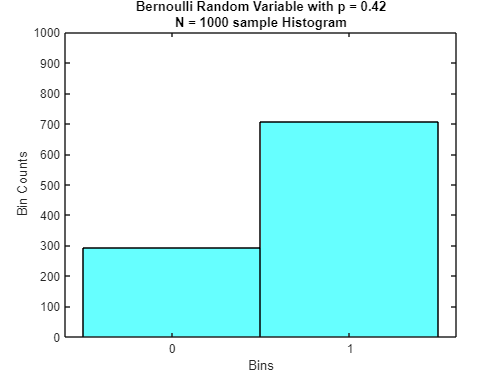

figure;
hist = histogram(sample_path,FaceColor="c");
title ({['Bernoulli Random Variable with p = ' num2str(p)], ...
    ['N = ' num2str(N) ' sample Histogram']});
ylim([0 N]);
xticks(0:1);
xlabel ('Bins')
ylabel ('Bin Counts')

### Generating multiple sample paths:

    Now that we have figured out how to generate a single sample path, we can generate multiple. We will generate `K` independent sample paths, each generated by re-running our experiment of generating `N` Bernoulli trials. We will represent our `K` sample paths with `N` trials as an `K`-by-`N` matrix, so that each row is a single sample path and we have `K` rows. 

- Call `randsample()` `K` times to generate `N` Bernoulli trials at each iteration of the `for` loop. Write these trials on the rows of the `multiple_paths` matrix variable.

K = 2000;
N = 1000;
multiple_paths = zeros([K N]);
for k = 1:K
    
    multiple_paths(k, :) = randsample([0 1],N,true,[1-p p]);

    
end

Anonymus function is written to to compute the probability for any given sample path

path_prob = @(sample_path) p^(sum(sample_path(:)))*(1-p)^(N-sum(sample_path(:)));

For each sample path in `multiple_paths` compute this probability by calling the anonymous function on each row.

path_probs = zeros(K, 1);
for k = 1:K
    
    path_probs(k) = path_prob(multiple_paths(k,:));
    
end

    Interestingly enough, most sample paths will have probability around $2^{-NH(p)}$, where $H(p)=p \log _2(1/p)+(1-p) \log _2 (1/(1-p))$ $H(p)$ is called the entropy of the coin in bits. You may check the results by clicking the variable "path_probs" located in the Workspace area (on the right of the screen as default).

### Estimation:

    Now that we know how to generate trials, let's do some parameter estimation. The probability of success will be estimated by dividing number of successes by the total number of trials. First estimator function that maps the observed trials to the estimate of the quantitiy in question is generated. An exapmle ***estimator() ***function can be viewed.

p_est = sum(sample_path)/N

p_est = 1.5500

p_est = estimator(sample_path)

p_est = "0.71594"

Success of the estimator is evaluated as a function of number of observations. Then plotted these estimates as a function of `n.`

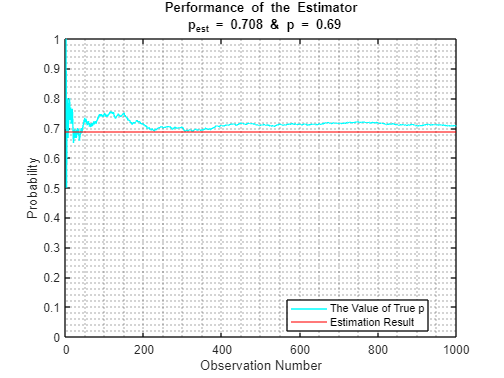

p = 0.69;
N = 1000;
sample_path = randsample([0 1],N,true,[1-p p]);


p_est_ = zeros(N, 1);

for n = 1:N
    
    p_est_(n) = estimator(sample_path(1:n));
    
end
figure;
plot(p_est_, Color='c');
hold on;
yline(p,'r');
ylim([0 1])
xlim([0 1000])
grid minor;
xlabel('Observation Number')
ylabel("Probability")
str = sprintf("Performance of the Estimator\n p_{est} = %.3f & p = %.2f" ...
    ,p_est_(N),p);
title(str);
legend("The Value of True p", "Estimation Result", Location="best")

    In this part, we will aim to evaluate the success of your estimator as a function of number of observations. For each `n`, we will compute an estimate over the first `n` samples. We will then plot these estimates as a function of `n`. Let us call this the *trajectory* of our estimator.

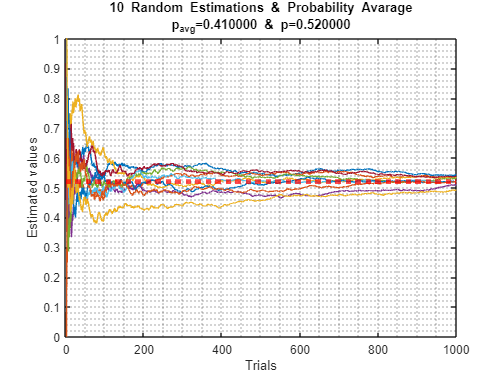

p = 0.52;
N = 1000;
K = 10;
zerovec=zeros(K,N);


p_est__ = zeros(K, N);
for t = 1:K
    
    zerovec(t,:) = randsample([0 1],N,true,[1-p p]);
    
end

for l = 1:K
    pred_data=randsample([0 1],N,true,[1-p p]);
    p_est_=zeros(size(pred_data));
    
    for n = 1:N
        
        p_est__(l,n) = estimator(zerovec(l,1:n));
        
    end
end


figure;
plot((p_est__)','LineWidth',0.75);
hold on;
yline(p,'r:','LineWidth',4);
grid minor;
xlabel("Trials")
ylabel("Estimated values")
counter=0;
for i=1:K
    
    counter=counter+p_est__(i,N);
end
counter = counter/10;
titlee = sprintf("10 Random Estimations & Probability Avarage\np_{avg}=" + ...
    "%f & p=%f",p_est__(N),p);
title(titlee);

Above method is run on `K` different sample paths and plotted the estimator trajectory for each of these.

**Question:** Comment briefly on the behaviour you observe on the plot created above. How does estimator perform as `n` increases? Do the plots vary from run to run? What are the similarities and differences between different runs?

**Answer:** As the number of trials rises, It can be observed that the estimator's output roughly approaches the true p value. As the number of trials (n) increases, the estimator function performs more accurately, as seen. As predicted, the probability factor causes the plots to differ on each run. One of the primary differences is that there are some obvious departures from the true value of p or some bumps brought on by successively identical results. Otherwise, the plots generally follow a similar path and converge to the true value of p.

Among these `K` sample paths there are some that are "atypical", in the sense that the proportion of 1's differs from the true parameter `p`. The folowing code is written to find the number of these atypical paths.

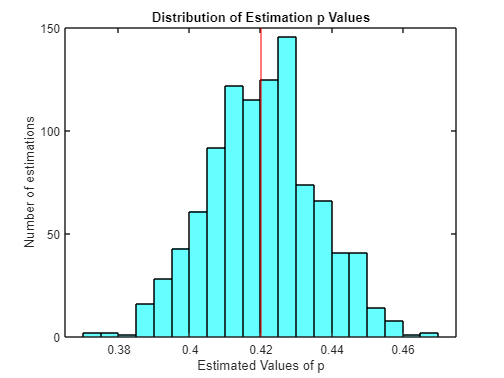

N = 1000; K = 1000;
p = 0.42;

for k = 1:K
    
    multiple_paths(k, :) = randsample([0 1],N,true,[1-p p]);
    
end
path_p_ests = zeros(K, 1);
for k = 1:K
    
    path_p_ests(k) = estimator(multiple_paths(k,:));
    
end

figure;
histogram(path_p_ests,FaceColor="c");
xline(p,'r','LineWidth',1.25);
xlabel("Estimated Values of p")
ylabel("Number of estimations")
title('Distribution of Estimation p Values')

The number of sample paths is calculated with estimated `p` values differing by 5% from the true one, i.e. with `p_est` values smaller than `0.95*p` or greater than `1.05*p`.

number_of_atypical = 0;
lenn=numel(path_p_ests);
for r=1:lenn
    if 0.95*p < path_p_ests(r,1) < 1.05*p
        
        number_of_atypical=number_of_atypical+1;
        
    end
    
end
display("The number of sample paths are differed 5 percent from real number which is " ...
    + num2str(number_of_atypical))

    "The number of sample paths are differed 5 percent from real number which is 79"



## Probabilistic Recursion and Binomial & Geometric Random Variables

### Preliminary Information: Recursion

    When the definition of a concept or process depends on a more basic version of itself, recursion has occurred. Recursion is used in many academic fields, including linguistics and logic. In mathematics and computer science, recursion is most frequently used when a function is defined and then used inside of its own definition. Recursion is a computational problem-solving technique used in computer science where the solution is dependent on solutions to smaller instances of the same problem. Recursion uses functions that call themselves from within their own code to solve such recursive problems. Recursion is a fundamental concept in computer science, and the approach can be used to solve a variety of problems.

The first thing that comes to mind when recursive function is mentioned is the factorial function denoted as 'n!' while n is a non negative integer.


$$n!\;=f\left(n\right)=1\cdot 2\cdot 3\cdots \left(n-2\right)\cdot \left(n-1\right)\cdot
n$$


A basic model of factorial implementation on MATLAB can be seen below.

Another implementation can be seen below

    The second implementation requires an extra argument res to keep track of the product, whereas the first implementation does not. This is how the two implementations differ from one another. The second implementation is typically regarded as being preferable because it makes better use of memory. Every time the function is called, it is accomplished by adding the results of previous steps. As a result, the second function uses less memory and can process larger inputs without running out of space.

### Binomial Random Variable

    The binomial random variable is a discrete random variable for the number of successes in N independent Bernoulli trials.

*K* ~ *Binom (n,p)* **then** $f\left(k\right)=\left(\underset{k}{n} \right)\cdot p^k \cdot {\left(1-p\right)}^{\left(n-k\right)}$ **for** *k = 0,...,n*

    Recall that the result of Bernoulli trials had been modelled in the previous homework to take the values 0 or 1, with respective probabilities and p. Then, by defining n Bernoulli random variables the number of successes can be expressed (meaning the number of 1's) as the sum of these random variables. Written more compactly form can be seen below.

$X_i \;\;$~ *Bernoulli (p)* **for** *i = 1,..., n and* $K=X_i +\cdots +X_n$ **then** *K* ~ *Binom (n,p)*

Note that the 's are independent of each other, because the result of each Bernoulli trial is independent of the others. Then, the summation with the first terms is also a binomial random variable, only this time it is the number of successes is trials and the probability success is the same, p. Denoting a Bernoulli random variable with n trials by , this fact can be written more compactly as follows:

**if** $K_{\left(n-1\right)}$ ~ *Binom (n-1, p)* **and** $X_n \;$~ *Bernoulli(p)* **are independent**

**with** $K_n =K_{\left(n-1\right)} +X_n$*, then* $K_n$ ~ *Binom (n, p)* Step 1. A simple function is written to generate a single Bernoulli trial, can be seen below. The function will take the probability of success p as input, and return the Bernoulli trial, i.e. either a 0 or a 1.

    Using the function written for the previous step, a recursive function is written that generates a single sample from *Binom (n, p)*, can be seen below. The inputs will be n and p as defined above, and the output will be a single integer.

- When *n = 1 my_binom_recur* function calls *my_bernoulli* function to generate a single Bernoulli trial with the probability of succes *p*.

- When *n > 1 my_binom_recur* function calls itself again with "n-1", and add a single Bernoulli trial to output. Same procces goes on until *n = 1.* Step 3. 1000 samples are generetad from *Binom (n=10, p=0.3)* by calling a *for* loop to call the function above.

for k = 1:1000
    firstSample(1,k) = my_binom_recur(10,0.3);
end    

A second set of 1000 samples are generetad from *Binom (n=10, p=0.3)* using the following code:

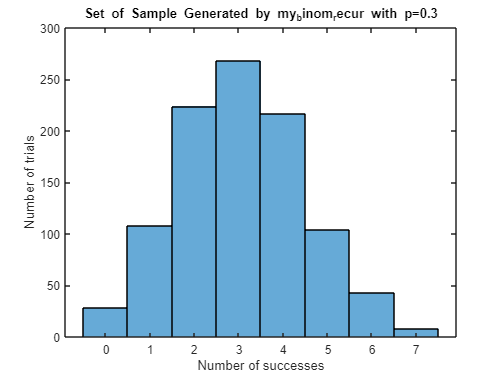

MATLAB_binom = makedist("binomial", N = 10, p = 0.3);
MATLAB_binom_samples = MATLAB_binom.random(1000, 1);

figure;
histogram(firstSample);
title("Set of Sample Generated by my_binom_recur with p=0.3")
xlabel("Number of successes");
ylabel("Number of trials");

Histogram of set of sample generated by *MATLAB_binom can be seen below.*

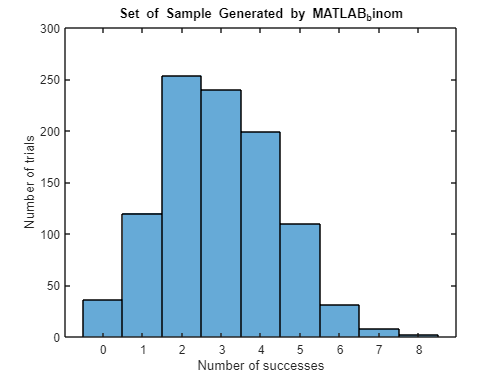

figure;
histogram(MATLAB_binom_samples);
title("Set of Sample Generated by MATLAB_binom")
xlabel("Number of successes");
ylabel("Number of trials");

Since histograms are considerably similar, The written binomial sampler can be deemed succesfull.

### Geometric Random Variable

    The geometric random variable *Genom(p)* denotes the number of trials up to and including the first success in a sequence of independent Bernoulli trials, each with probability of success *p*. The following anonymus function is to generate M independent and identical Bernoulli trials, each with success probability p, and put them in a vector. By the first description of the geometric random variable, the length of the initial segment up to and including the first 1 of this vector is a geometric random variable.


my_geom_bad = @(M,p) find(randsample([0 1],M,true,[1-p p]),1,"first");


1000 samples are generated from *Geom(p=0.3)* by calling a *for* loop to call the function above.

for k = 1:1000
    firstGeoSample(1,k) = my_geom_recur(0.3, 1);
end

1000 samples are generated from *Geom(p=0.3)* by the code written below.

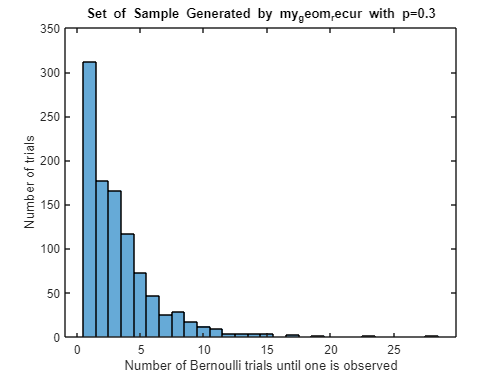

MATLAB_geom_samples = 1 + geornd(0.3, 1000, 1);
% Histogram of set of sample generated by _my_geom_recur can be seen below._

figure;
histogram(firstGeoSample);
title("Set of Sample Generated by my_geom_recur with p=0.3")
xlabel("Number of Bernoulli trials until one is observed");
ylabel("Number of trials");

Histogram of set of sample generated by the code piece can be seen below.

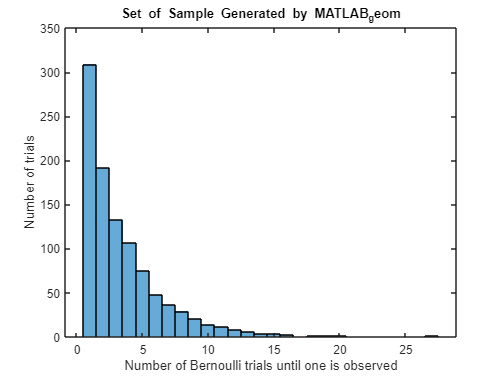

figure (4);
histogram(MATLAB_geom_samples)
title("Set of Sample Generated by MATLAB_geom")
xlabel("Number of Bernoulli trials until one is observed");
ylabel("Number of trials");

Since histograms are considerably similar, The written geometric sampler can be deemed succesfull.

**Question 1**: The naming for the first, non-recursive implementation of the geometric sampler in Part II Step 1 is  not a coincidence: It is called my_geom_bad because it is a bad sampler, in that there are cases where its output  may not be a valid geometric random sample. Why do you think this is? Knowing the value of p and M, what  outputs of my_geom_bad(M, p) should make you suspicious, and with what probability are they valid? 

**Answer to 1st Question:** It is possible that all M trials give 0 output. When this occurs *my_geom_bad* cannot be valid. As output gets closer to M, it becomes more suspicious. *my_geom_bad* is valid with probability $1-{\left(1-p\right)}^M$.

**Question 2:** You've coded two recursive functions, in that each function makes a call to itself, within itself.  However, the two implementations differ in one crucial way: The recursive implementation of the binomial  4 sampler here will always call itself N times, and then will return its output. The recursive implementation of the  geometric sampler, however, has no such guarantee; it can call itself recursively a different number of times  each time you call it.

**Answer to 2nd Question:** In *my_binom_recur,* the function have to check all the path in order to find all *ones*. In contrast to that, *my_geom_recur* stops when it finds a *one,* so ; it can call itself recursively a different number of times each time it is called.

**Question 3:** Knowing the value of p, what random variable describes the number of recursive calls  my_geom_recur will make? What is its expectation?

**Answer to 3rd Question:** $P_k \left(k\right)={p\cdot \left(1-p\right)}^{\left(k-1\right)}$ is the probability function of the random variable describes the number of recursive calls my_geom_recur will make for k=1,2,...,n. Expectation of this random variable can be calculated by the formula: $\sum_{k=1}^n k\cdot p\cdot {\left(1-p\right)}^{\left(k-1\right)}$

**Question 4:** Since we know that the number of recursive calls my_geom_recur will make is a random variable,  there may not be a guarantee that it will stop at a finite time, which would be a very unfortunate property for  a function. Knowing the value of p, express the probabilty that my_geom_recur(p) will not stop its recursion  within M recursive function calls. To which value does this probability converge (if it does) as $M\longrightarrow \infty$ ? What do you conclude from this result?

**Answer to 4th Question:** Since probability of unvalidity is ${\left(1-p\right)}^M$ it also means the probabilty that *my_geom_recur(p)* will not stop its recursion within M recursive function calls. for all $0<p\le 1,\lim_{M\longrightarrow \infty } {\left(1-p\right)}^M =0$, that means loop should stop at some time, but for p = 0 $\lim_{M\longrightarrow \infty } {\left(1-p\right)}^M =1\;$means the loop will never stop.

**Question 5:** Preferable to its alternative in this assignment it may be, my_geom_recur is still far from ideal.  Comment on its computation time as compared to MATLAB's implementation. For which values of p does this  computation time get worse?

**Answer to 5th Question:** The observations indicated that the MATLAB implementation is considerably faster than the hand-written functions. This is the result of recursive functions making an excessive number of calls to find the answer, which may lengthen computation time. The expected number of trials before the first success is high when p is close to 0 (the probability of success is low), and the recursion may need to last for a long time, increasing the computation time.

## Parametric & Non-Parametric Density Estimation and Normal(Gaussian) Random Variable

### Intro & Warm-up: Gaussian PDF

This task is an attempt of estimating the underlying density, also named "density estimation". It has to be stated that this is still an active research area. Firstly, Gaussian Random Variable should be defined. Gaussian Random variable is uniquely defined by its mean $\mu$ and variance $\sigma^2$ (or equivalently, its standard deviation $\sigma$). For a Gaussian random variable *X*, denoted $X\sim N\left(\mu ,\sigma^2 \right)$ , the PDF is given as


$$$f_x \left(x\right)=\frac{1}{\sqrt{2\pi \sigma^2 }}\exp \left(-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }\right)$$


    A 1-by-4 empty cell-array is created, then set each element to a normal distribution with 4 random variables such that "$X_1 \sim N\left(\mu \;=\;2,\;\sigma \;=1\right)$ , $X_2 \sim N\left(\mu \;=\;-2,\;\sigma \;=1\right)$, $X_3 \sim N\left(\mu \;=\;0,\;\sigma \;=1\right)$, $X_4 \sim N\left(\mu \;=\;0,\;\sigma \;=2\right)$". Note that the second parameter is $\sigma$, not $\sigma^2$. Then, a 2-by-2 tiled layout is created to plot the PDFs. In this part, to obtain the gaussian random variable, a handmade function is used.

Alternatively, "normpdf" function or any applicable functions can be used.

The following code block includes cell-array creation and 2-by-2 tiled layout creation. Since MATLAB works on discrete space, x axis defined as written on the code block. The reason x axis increases by 0.01 unit is to obtain a similar graph to the function defined on continuous space.

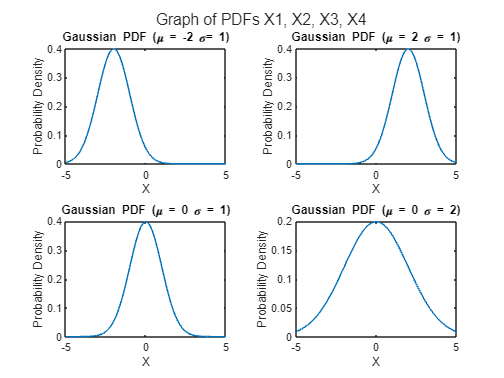

cell_array = cell(1,4);  % create an empty cell array of size 1-by-4

cell_array{1} = makedist('Normal','mu',-2,'sigma',1);  % set each element of the cell array to a NormalDistribution object
cell_array{2} = makedist('Normal','mu',2,'sigma',1);
cell_array{3} = makedist('Normal','mu',0,'sigma',1);
cell_array{4} = makedist('Normal','mu',0,'sigma',2);

% x axis creation
xaxis = linspace(-5, 5, 1000);
% Create a 2-by-2 tiled layout
figure;
tiled_layout_1 = tiledlayout(2,2);
% Plot the first figure in the top-left tile
nexttile;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{1}.mu, cell_array{1}.sigma));
xlabel('X')
ylabel('Probability Density')
title('Gaussian PDF (\mu = -2 \sigma= 1)');

% Plot the second figure in the top-right tile
nexttile;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{2}.mu, cell_array{2}.sigma));
xlabel('X')
ylabel('Probability Density')
title('Gaussian PDF (\mu = 2 \sigma = 1)');

% Plot the third figure in the bottom-left tile
nexttile;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{3}.mu, cell_array{3}.sigma));
xlabel('X')
ylabel('Probability Density')
title('Gaussian PDF (\mu = 0 \sigma = 1)');

% Plot the fourth figure in the bottom-right tile
nexttile;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{4}.mu, cell_array{4}.sigma));
xlabel('X')
ylabel('Probability Density')
title('Gaussian PDF (\mu = 0 \sigma = 2)');

% Title of the entire layout
sgtitle("Graph of PDFs X1, X2, X3, X4")


% For each of these random variables, 1000 independent samples is created with
% normrnd function.

% Generate 1000 samples from a Gaussian distribution
samples1 = normrnd(-2, 1, 1000, 1);
samples2 = normrnd(2, 1, 1000, 1);
samples3 = normrnd(0, 1, 1000, 1);
samples4 = normrnd(0, 2, 1000, 1);

    A 2-by-2 tiled layout is created to show the histogram of created samples and plotted graphs of PDFs on same figure. It can be noticed that the scale of y-axis starts from 0 and goes to 100 which is inappropriate to a PDF, because for validity of the PDF the sum of orange colored areas must be equal to 1. It can be denoted as;


$$\int_{-\infty }^{\infty } f_x \left(x\right)\textrm{dx}=1$$


    In this histogram y axis shows us number of observation in other words raw count not the PDF.

    The effects of mean, variance, and standard deviation were additionally seen. The point on the PDF graph with the highest possible y-value corresponds to the x-value of the Gaussian distribution's mean. The Gaussian distribution's standard deviation could be reduced or raised to make the distribution curve shorter or taller, respectively. The area beneath it still equals 1, and the PDF is still valid. Theoriticaly the range of the mean($\mu$) is $\left(-\infty ,\infty \right)$ and the range of standart deviation($\sigma$) is $\left(0,\infty \right)\ldotp$Nevertheless, depending on the question, the range of the mean and standard deviation might be altered.

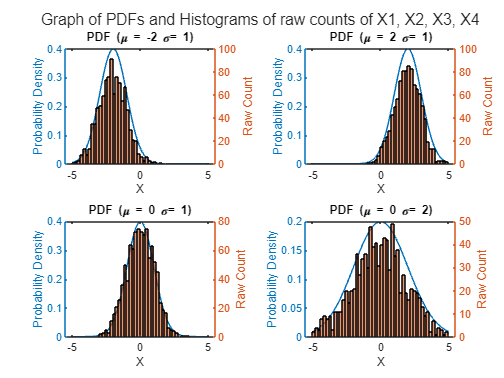

figure;

tiled_layout_2 = tiledlayout(2, 2);

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{1}.mu, cell_array{1}.sigma));
ylabel('Probability Density');

yyaxis right;
histogram(samples1, 'Normalization', 'count', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Raw Count')
title('PDF (\mu = -2 \sigma= 1)');

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{2}.mu, cell_array{2}.sigma));
ylabel('Probability Density');

yyaxis right
histogram(samples2, 'Normalization', 'count', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Raw Count')
title('PDF (\mu = 2 \sigma= 1)');

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{3}.mu, cell_array{3}.sigma));
ylabel('Probability Density');

yyaxis right;
histogram(samples3, 'Normalization', 'count', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Raw Count')
title('PDF (\mu = 0 \sigma= 1)');

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{4}.mu, cell_array{4}.sigma));
ylabel('Probability Density');

yyaxis right;
histogram(samples4, 'Normalization', 'count', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Raw Count')
title('PDF (\mu = 0 \sigma= 2)');

sgtitle("Graph of PDFs and Histograms of raw counts of X1, X2, X3, X4")

Now, same procedure repeated while histogram is set to Normalization = "pdf". When Normalization setting to 'pdf' the sum of orange colored areas to 1. The histogram is scaled so that the bin heights represent probability densities rather than raw counts. This is achieved by dividing the height of each bin by the total number of data points and the width of the corresponding bin. In other words, if you have a set of data and you create a histogram with `'pdf'` normalization, the y-axis represents the probability density instead of the raw count. The area under the histogram curve will sum up to 1, indicating the probability of a data point falling within each bin. This normalization is useful when comparing histograms of different datasets or when you want to analyze the shape of the distribution without being affected by the total number of data points.

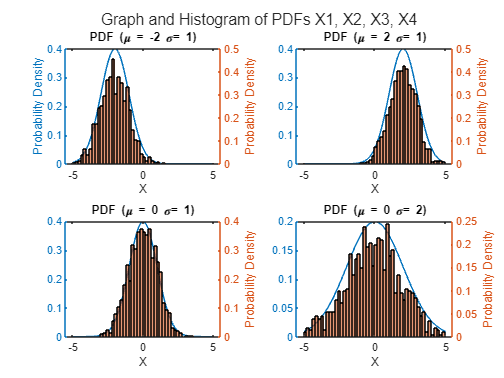

figure;

tiled_layout_3 = tiledlayout(2, 2);

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{1}.mu, cell_array{1}.sigma));
ylabel('Probability Density')

yyaxis right;
histogram(samples1, 'Normalization', 'pdf', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Probability Density')
title('PDF (\mu = -2 \sigma= 1)');

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{2}.mu, cell_array{2}.sigma));


yyaxis right
histogram(samples2, 'Normalization', 'pdf', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Probability Density')
title('PDF (\mu = 2 \sigma= 1)');

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{3}.mu, cell_array{3}.sigma));

yyaxis right;
histogram(samples3, 'Normalization', 'pdf', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Probability Density')
title('PDF (\mu = 0 \sigma= 1)');

nexttile;
yyaxis left;
plot(xaxis, gauss_pdf_func(xaxis, cell_array{4}.mu, cell_array{4}.sigma));

yyaxis right;
histogram(samples4, 'Normalization', 'pdf', 'BinWidth', 0.2, 'BinLimits', [-5 5]);
xlabel('X')
ylabel('Probability Density')
title('PDF (\mu = 0 \sigma= 2)');

sgtitle("Graph and Histogram of PDFs X1, X2, X3, X4")

    In order to create a Gaussian Random Variable, a NormalDistribution object is created with $N\sim \left(\mu_{\textrm{true}} =2\ldotp 5,{\;\sigma }_{\textrm{true}} =\sqrt{6\ldotp 5}\right)$ and 1000 independent identically distributed samples is taken.This random variable will be used in the following parts too.


willBeEstimated = random(makedist('Normal', mu=2.5, sigma=(6.5)^(1/2)), 1000, 1);
% In the following parts, there will be attempts to estimate "willBeEstimated" random
% variable.

### Parametric Density Estimation

In this part a parametric density estimator will be built. Parametric density estimating means it will be assumed a form to the underlying PDF that is tried to estimate, and will be found its parameters (hence the name) out of the samples. To approximate the underlying density of a set of samples with a Gaussian, where are the samples for  $n=1,2,\ldotp \ldotp \ldotp ,N\;$, their empirical/sample mean and standard deviation , denoted $\bar{\mu}$ and $\bar{\sigma}$, will be computed as follows:


$$\bar{\mu} =\frac{1}{N}\sum_{n=1}^{\;N} X_n$$



$$\bar{\sigma} =\sqrt{\frac{1}{N-1}\sum_{n=1}^N {\left(X_n \;-\bar{\mu} \right)}^2
}$$


Therefore the estimated PDF, which will be denoted as ${\tilde{f} }_{\textrm{Gaussian}} \left(x\right)$, will be given as


$${\tilde{f} }_{\textrm{Gaussian}} \left(x\right)=\frac{1}{\sqrt{2\pi \sigma^2
}}\exp \left(-\frac{{\left(x-\bar{\mu} \right)}^2 }{2{\bar{\sigma} }^2 }\right)$$


where $\bar{\mu}$ and $\bar{\sigma}$ are computed as above Step 1: Two anonymous functions are written to estimate the mean and standart deviation due to formulas above. Sum and length function is used to write the formula on code.

% Custom function to calculate the empirical mean
empiric_mean = @(input) sum(input) / length(input);

% Custom function to calculate the empirical standard deviation
empiric_std = @(input) sqrt(sum((input - empiric_mean(input)).^2) / (length(input) - 1));

    A 2-by-2 tiled layout is created. On each of these tiles, The true pdf and estimated pdf are plotted with the parameters calculated with the functions from Step 1 that uses the first $N_i$ samples on each tile, where $N_i$ is set to 2, 10, 100 and 1000. For that purpose _sample_vector_mert_ vector is created.

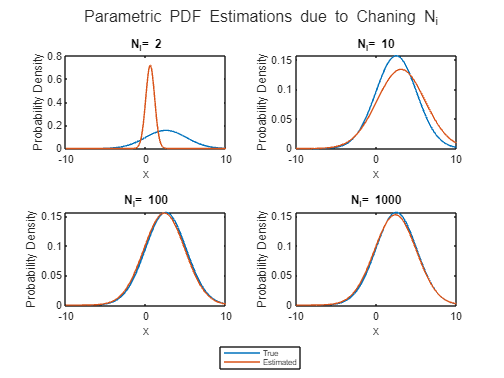


sample_vector = [2 10 100 1000];

x = linspace(-10,10,1000);
real_pdf = pdf(makedist('Normal', mu=2.5, sigma=(6.5)^(1/2)), x);
figure(4);
tiled_layout_4 = tiledlayout(2, 2);

nexttile;
plot(x, real_pdf);
hold on;
e_mean = empiric_mean(willBeEstimated(1:sample_vector(1)));
e_std = empiric_std(willBeEstimated(1:sample_vector(1)));
y2 = pdf(makedist('Normal', mu=e_mean, sigma=e_std), x);
plot(x,y2);
title("N_i= 2");
xlabel('x');
ylabel('Probability Density');

nexttile;
plot(x, real_pdf);
hold on;
e_mean = empiric_mean(willBeEstimated(1:sample_vector(2)));
e_std = empiric_std(willBeEstimated(1:sample_vector(2)));
y2 = pdf(makedist('Normal', mu=e_mean, sigma=e_std), x);
plot(x,y2);
title("N_i= 10");
xlabel('x');
ylabel('Probability Density');

nexttile;
plot(x, real_pdf);
hold on;
e_mean = empiric_mean(willBeEstimated(1:sample_vector(3)));
e_std = empiric_std(willBeEstimated(1:sample_vector(3)));
y2 = pdf(makedist('Normal', mu=e_mean, sigma=e_std), x);
plot(x,y2);
title("N_i= 100");
xlabel('x');
ylabel('Probability Density');

nexttile;
plot(x, real_pdf);
hold on;
e_mean = empiric_mean(willBeEstimated(1:sample_vector(4)));
e_std = empiric_std(willBeEstimated(1:sample_vector(4)));
y2 = pdf(makedist('Normal', mu=e_mean, sigma=e_std), x);
plot(x,y2);
title("N_i= 1000");
xlabel('x');
ylabel('Probability Density');

sgtitle("Parametric PDF Estimations due to Chaning N_i");
legg = legend("True","Estimated",'Location','southwest','FontSize',6.25);
legg.Layout.Tile = 'south';

    It can be observed that as the empirical mean and standard deviation values got closer to their true values, the estimated PDF's precision increased with the number of samples. Furthermore, It has been found that relying on the random values they got, the estimated PDF with 2 and 10 samples could either be very accurate or very inaccurate.

    It can also be noticed that the scale of x-values have to be customized when handling with a custom true PDF. As $\overline{\mu}$ symbolizes the center of the PDF graph and $\overline{\sigma$ symbolizes the distribution over the x-axis, the scale of x-values might be larger if is $\overline{\sigma$ large and may also include the $\overline{\mu}$ value. Determining a range of $[\overline{\mu}_{true}-5\overline{\sigma}_{true},\overline{\mu}_{true}+5\overline{\sigma}_{true},]$ is a proper option because, the Gaussian distribution contains approximately 99.7% of the values within the range of three standard deviations ($\pm3\overline{\sigma$) from its center.

### Non-Parametric Density Estimation

In this part a non-parametric density estimation which is called *kernel density estimation(KDE)* will be tried to implement. In KDE, the equally weighted sum of each sample is taken and replaced with a Gaussian density with a chosen standard deviation will denoted as $\beta$. Therefore, the estimated underlying PDF $\widetilde{f}_{KDE}(x)$ is constructed as follows:


$$\widetilde{f}_{KDE}(x) = \frac{1}{N}\sum_{n=1}^{N} \frac{1}{\sqrt{2\pi\beta^2}}exp(-\frac{(x-X_n)^2}{2\beta^2})$$


where $$X_n $ are the samples for $n = 1,...,N$ and $\beta$ is the chosen standard deviation. Step 1: obligations for validity of$\widetilde{f}_{KDE}(x)$:

- Non-negativity: as ${\overset{～}{f} }_{KDE} (x)\ge 0$ for all values of x.

- Normalization: The integral of the PDF over its entire domain must equal 1. $\int_{-\infty}^{+\infty} \widetilde{f}_{KDE}(x) = 1$

Since MATLAB works on discrete space, Integration is changed by the *sum()* and domain is restricted between *-1000 to 1000*.

normalization = sum((KDE_pdf(-1000:1000,willBeEstimated,0.5)))

normalization = 0.9996

    A function called _KDE_pdf()_ is written, whose inputs are x, samples, and beta.  X is a vector of dummy variables where the estimated PDF is to be evaluated. Samples contain the random samples $X_n \;$ whose underlying PDF is tried to find, and beta is the standard deviation of the Gaussian kernel. The function is written as follows:

Step 3: A 2-by-2 tiled layout is created and on each of the tiles, the true PDF and the estimated PDF is plotted by using KDE_pdf() for $\beta = 0.5$ and the first $\textit{N}_i$ samples on each tile, where $\textit{N}_i$ is set to 2, 10, 100 and 1000. Accoring to the observations, It can be noticed that the estimated PDF gets closer to the true PDF as the number of samples is increased. This implies that the precision of the PDF estimation could be raised by increasing the number of samples. The conclusions has been made point to the promience of sample size to made an accurate density estimatior.

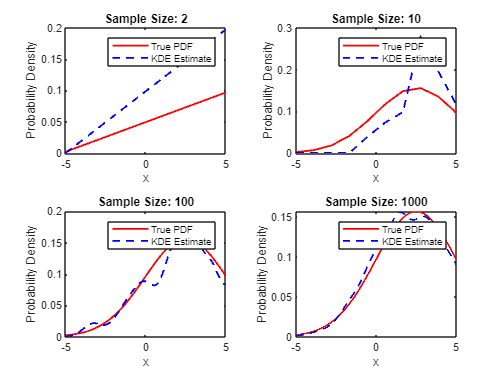

beta = 0.5;

figure;
tiledstep3 = tiledlayout(2, 2);

% A for loop is used to ease the writing of each tile(It could be better if
% I've noticed this easy way in previous parts :))
for i = 1:numel(sample_vector)
    nexttile;
    
    true_mean = 2.5;
    true_variance = 6.5;
    true_samples = normrnd(true_mean, sqrt(true_variance), sample_vector(i), 1);
    
    x_values = linspace(-5, 5, sample_vector(i));
    kde_est = KDE_pdf(x_values, true_samples, beta);
    
    true_pdf = normpdf(x_values, true_mean, sqrt(true_variance));
    plot(x_values, true_pdf, 'r-', 'LineWidth', 1.5);
    hold on;
    plot(x_values, kde_est, 'b--', 'LineWidth', 1.5);
    hold off;
    
    title(['Sample Size: ' num2str(sample_vector(i))]);
    xlabel('x')
    ylabel('Probability Density')
    legend('True PDF', 'KDE Estimate');
end

In this step, the number of samples is fixed and the $\beta$ values is varied. A 2-by-2 tiled layout is created and on each of the tiles, the true PDF and the estimated PDF, using the KDE_pdf() function, is written by using 1000 samples and setting $\beta$ to 0.05, 0.1, 0.5 and 1 is plotted on each tile. It is clear that as the $\beta \;$values increase, the kernels get wider and the estimated density becomes smoother. This may help to analyze the overall shape of the underlying PDF.

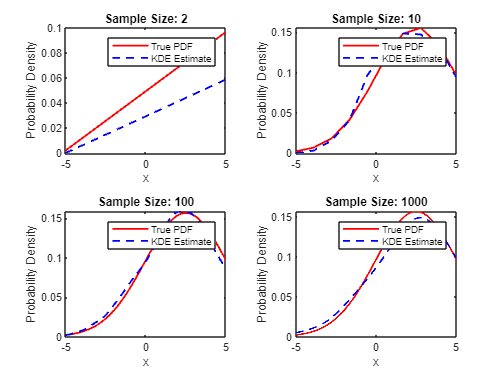


betas = [0.05 0.1 0.5 1];
figure;
tiledstep4 = tiledlayout(2, 2);

for i = 1:numel(sample_vector)
    nexttile;
    
    true_mean = 2.5;
    true_variance = 6.5;
    true_samples = normrnd(true_mean, sqrt(true_variance), 1000, 1);
    
    x_values = linspace(-5, 5, sample_vector(i));
    kde_est = KDE_pdf(x_values, true_samples, betas(i));
    
    true_pdf = normpdf(x_values, true_mean, sqrt(true_variance));
    plot(x_values, true_pdf, 'r-', 'LineWidth', 1.5);
    hold on;
    plot(x_values, kde_est, 'b--', 'LineWidth', 1.5);
    hold off;
    
    title(['Sample Size: ' num2str(sample_vector(i))]);
    xlabel('x')
    ylabel('Probability Density')
    legend('True PDF', 'KDE Estimate');
end

**Question 1: **What are the benefits and downsides of the two approaches? Which method is more flexible/expressive?

Advantages of Parametric Density Estimation:

- It is more expressive and simpler to use once it is assumed the form of the distribution.

- Because there are fewer "for" loops, it is effective for dealing with bigger amounts of data.

Parametric density estimation's drawbacks:

- If the distribution's shape is not accurately established, the estimation is likely to be considerably off.

- It only applies to specific distribution types.

Non-Parametric Density Estimation Benefits:

- It is more adaptive because it may be used with any type of distribution.

- Given that it makes no guesses, its estimation is likely to be accurate.

Non-Parametric Density Estimation Drawbacks:

- It needs an excessive number of calculations, which could make working with big amounts of data ineffective.

- The selection of a suitable parameter, which is necessary for an accurate outcome, is difficult.

Parametric density estimation is likely to fail if the underlying distribution is unknown and is not assumed appropriately. Non-parametric density estimation is more appropriate in these situations due to its increased flexibility. The memory management and calculation time may be a difficulty to overcome if we wish to employ a non-parametric technique while working with large data because this approach necessitates more computations and memory.

 **Question 2: **Let's try to compare the performance of the two approaches you implemented by inspection. On  the same figure, plot the true pdf and the estimations. Comment on the differences: What characteristics are  sufficiently well-expressed by the estimated PDFs in which case?

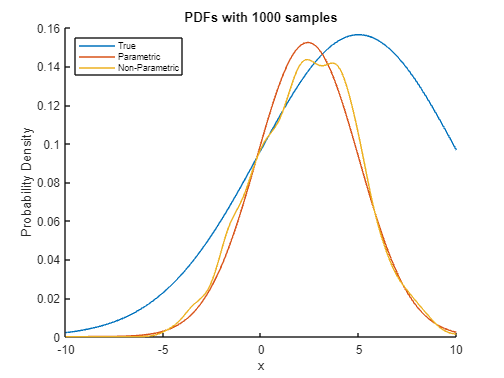

figure;
hold on;
plot(x, true_pdf);
e_mean = empiric_mean(willBeEstimated);
e_std = empiric_std(willBeEstimated);
y2 = pdf(makedist('Normal', mu=e_mean, sigma=e_std), x);
plot(x, y2);
plot(x, KDE_pdf(x, willBeEstimated,0.5));
title("PDFs with 1000 samples");
ylabel('Probability Density');
xlabel("x");
legend("True","Parametric","Non-Parametric",'Location',"northwest","FontSize",7.25);

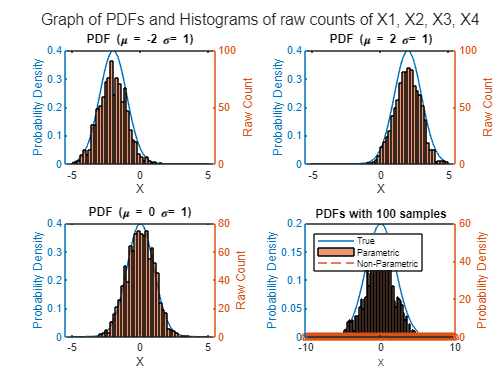

rangeOfX2= linspace(-10,10,100);
true_pdfofpart4 = normpdf(rangeOfX2, true_mean, sqrt(true_variance));
sample5 = random(makedist('Normal', 'mu', true_mean, 'sigma', sqrt(true_variance)), 100, 1);
figure(9);
hold on;
plot(rangeOfX2,true_pdfofpart4);
e_std3  = empiric_std(sample5);
e_mean3 = empiric_mean(sample5);
y3 = pdf(makedist('Normal', mu=e_mean3, sigma=e_std3), rangeOfX2);
plot(rangeOfX2, y3);
kde_est2 = KDE_pdf(rangeOfX2, sample5, 0.5);
plot(rangeOfX2, kde_est2);
title('PDFs with 100 samples')
xlabel('x')
ylabel('Probability Density')
legend("True","Parametric","Non-Parametric",'Location',"northwest","FontSize",7.25);

.In comparison to the PDF estimated by only 100 samples, it is seen that the one estimated using 1000 samples is more precise, smoother, and more accurately captures the features of the genuine underlying distribution. The fundamental properties of the underlying PDF may still be represented by the PDF that was computed using 100 samples, albeit with less specificity. Additionally, since the parametric PDF is computed using the distributions' forms, it is more accurate. Question 3: Less sampled situations are more likely to be impacted by the intrinsic randomness of the problem. With 2, 10, or 100 samples, the computed PDFs show greater variability. As a result, due to the problem's predicted randomness, they can be extremely accurate in one run and extremely inaccurate in another. Contrarily, the estimated PDF obtained from 1000 samples is more stable because the minor deviations have little impact on it.

## Appendix Function Declarations

function [p_est] = estimator(trials)
len = numel(trials);
p_est= string(sum(trials(:))/len);

end
function [bernoulli_sample] = my_bernoulli(p)
bernoulli_sample = randsample([0 1],1,true,[1-p p]);
end



function [binom_sample] = my_binom_recur(n, p)


if n == 1
    binom_sample = my_bernoulli(p);
else
    aa=exist("binom_sample");
    if aa==1
        
        binom_sample = binom_sample + my_binom_recur(n-1, p);
    else
        binom_sample = my_bernoulli(p)+my_binom_recur(n-1, p);
    end
    
    
end

end

function [geomRecur] = my_geom_recur(p, n)
countt = my_bernoulli(p);
if countt == 0
    geomRecur = my_geom_recur(p, n+1);
elseif countt == 1
    geomRecur = n;
    
end

end

function [est_pdf] = KDE_pdf(x, samples, beta)

n = length(samples);

est_pdf = zeros(size(x));

for i = 1:n
    est_pdf = est_pdf + (1/(beta*sqrt(2*pi))) * exp(-((x - samples(i)).^2) / (2*beta^2));
end
est_pdf = est_pdf/n;

end

function [gauss_pdf] = gauss_pdf_func(x, m, s)

gauss_pdf = 1./(sqrt(2*pi).*s) .* exp(-((x-m).^2)./(2.*s.^2));

end
